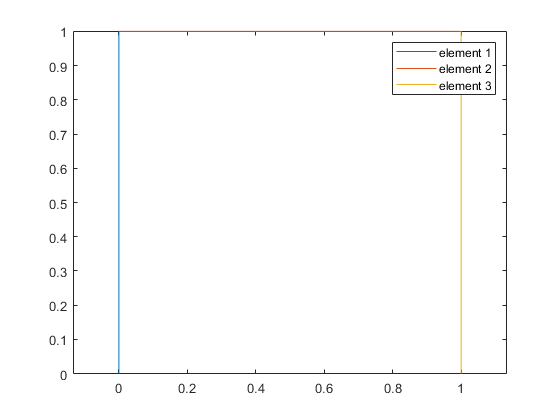

clc
clear % clear memory
tic       % starts a stopwatch timer
syms A E L I 

%number of nodes
num_nod=4;

% nodes coordinates [x1 y1;x2 y2 ...]
nod_coor=[0,0;0,1;1,1;1,0];

% elements nodes [start1 end 1;start2 end2;...]
ele_nod=[1,2;2,3;3,4];

%number of elements
num_ele=size(ele_nod,1);

%plotting shape
plot_shape(ele_nod,nod_coor)

%initialising data
horizontal_dof=zeros(1,num_nod);
vertical_dof=zeros(1,num_nod);
rotational_dof=zeros(1,num_nod);

% nodal degree of freedom (DOF)         1 for free 0 for not free 
for k=1:num_nod
    prompt_horizontal=sprintf('horizontal dof for node %0.0f \n',k);
    prompt_vertical=sprintf('vertical dof for node %0.0f \n',k);
    prompt_rotational=sprintf('rotational dof for node %0.0f \n',k);
    horizontal_dof(k)=input(prompt_horizontal);
    vertical_dof(k)=input(prompt_vertical);
    rotational_dof(k)=input(prompt_rotational);
end


% A, E, L,I are cross sectional area, Young's modulus, length of elements,moment of inertia respectively.

%initialising factors
Area_factor=zeros(1,num_ele);
E_factor=zeros(1,num_ele);
I_factor=zeros(1,num_ele);

identical=input(sprintf('do all elements have the same EI and A')); %one if yes
I_check=input(sprintf('is I 0')); %one if yes

for i=1:num_ele
    if identical==1
        Area_factor(i)=1;
        E_factor(i)=1;
    else 
        Area_factor(i)=input(sprintf('area for element %0.0f in terms of A \n',i));
        E_factor(i)=input(sprintf('youngs modulus for element %0.0f in terms of E \n',i));
    end
    
    if I_check==1
        I_factor(i)=0;
    elseif identical==1
        I_factor(i)=1;
    else 
        I_factor(i)=input(sprintf('moment of area for element %0.0f in terms of I \n',i)); 
    end
    
end

% initial zero matrix for all matrices
stiffness=sym(zeros(3*num_nod));

% computation of the system stiffness matrix
for e=1:num_ele
    L_factor=sqrt((nod_coor(ele_nod(e,2),1)-nod_coor(ele_nod(e,1),1))^2+...
      (nod_coor(ele_nod(e,2),2)-nod_coor(ele_nod(e,1),2))^2);
    C=(nod_coor(ele_nod(e,2),1)-nod_coor(ele_nod(e,1),1))/L_factor;
    S=(nod_coor(ele_nod(e,2),2)-nod_coor(ele_nod(e,1),2))/L_factor;
    T=[C S 0
     -S C 0
     0 0 1];
    R=[T zeros(3);zeros(3) T];
    fprintf('\n \n  local stiffness matrix for element %0.0f',e)
     k_local=getK(L*L_factor,E*E_factor(e),I*I_factor(e),A*Area_factor(e))
     fprintf('global stiffness matrix for element %0.0f',e)
     K_global=R\k_local*R
        for i=1:2
             row_offset=3*(ele_nod(e,i)-1);
            for j=1:2
                 collumn_offset=3*(ele_nod(e,j)-1);
                 stiffness(1+row_offset:3+row_offset,1+collumn_offset:3+collumn_offset)=stiffness(1+row_offset:3+row_offset,1+collumn_offset:3+collumn_offset)+K_global(3*(i-1)+(1:3),3*(j-1)+(1:3));
            end
        end
end


 
  local stiffness matrix for element 1

$$k\_local = \begin{array}{l} \left(\begin{array}{cccccc} \sigma_{3} & 0 & 0 & -\sigma_{3} & 0 & 0\\ 0 & \sigma_{2} & \sigma_{1} & 0 & -\sigma_{2} & \sigma_{1}\\ 0 & \sigma_{1} & \frac{4\,\text{E}\,\text{I}}{L} & 0 & -\sigma_{1} & \frac{2\,\text{E}\,\text{I}}{L}\\ -\sigma_{3} & 0 & 0 & \sigma_{3} & 0 & 0\\ 0 & -\sigma_{2} & -\sigma_{1} & 0 & \sigma_{2} & -\sigma_{1}\\ 0 & \sigma_{1} & \frac{2\,\text{E}\,\text{I}}{L} & 0 & -\sigma_{1} & \frac{4\,\text{E}\,\text{I}}{L} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{6\,\text{E}\,\text{I}}{L^{2}}\\ \sigma_{2}=\frac{12\,\text{E}\,\text{I}}{L^{3}}\\ \sigma_{3}=\frac{A\,\text{E}}{L} \end{array}$$

global stiffness matrix for element 1

$$K\_global = \begin{array}{l} \left(\begin{array}{cccccc} \sigma_{2} & 0 & -\sigma_{1} & -\sigma_{2} & 0 & -\sigma_{1}\\ 0 & \sigma_{3} & 0 & 0 & -\sigma_{3} & 0\\ -\sigma_{1} & 0 & \frac{4\,\text{E}\,\text{I}}{L} & \sigma_{1} & 0 & \frac{2\,\text{E}\,\text{I}}{L}\\ -\sigma_{2} & 0 & \sigma_{1} & \sigma_{2} & 0 & \sigma_{1}\\ 0 & -\sigma_{3} & 0 & 0 & \sigma_{3} & 0\\ -\sigma_{1} & 0 & \frac{2\,\text{E}\,\text{I}}{L} & \sigma_{1} & 0 & \frac{4\,\text{E}\,\text{I}}{L} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{6\,\text{E}\,\text{I}}{L^{2}}\\ \sigma_{2}=\frac{12\,\text{E}\,\text{I}}{L^{3}}\\ \sigma_{3}=\frac{A\,\text{E}}{L} \end{array}$$


 
  local stiffness matrix for element 2

$$k\_local = \begin{array}{l} \left(\begin{array}{cccccc} \sigma_{3} & 0 & 0 & -\sigma_{3} & 0 & 0\\ 0 & \sigma_{2} & \sigma_{1} & 0 & -\sigma_{2} & \sigma_{1}\\ 0 & \sigma_{1} & \frac{4\,\text{E}\,\text{I}}{L} & 0 & -\sigma_{1} & \frac{2\,\text{E}\,\text{I}}{L}\\ -\sigma_{3} & 0 & 0 & \sigma_{3} & 0 & 0\\ 0 & -\sigma_{2} & -\sigma_{1} & 0 & \sigma_{2} & -\sigma_{1}\\ 0 & \sigma_{1} & \frac{2\,\text{E}\,\text{I}}{L} & 0 & -\sigma_{1} & \frac{4\,\text{E}\,\text{I}}{L} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{6\,\text{E}\,\text{I}}{L^{2}}\\ \sigma_{2}=\frac{12\,\text{E}\,\text{I}}{L^{3}}\\ \sigma_{3}=\frac{A\,\text{E}}{L} \end{array}$$

global stiffness matrix for element 2

$$K\_global = \begin{array}{l} \left(\begin{array}{cccccc} \sigma_{3} & 0 & 0 & -\sigma_{3} & 0 & 0\\ 0 & \sigma_{2} & \sigma_{1} & 0 & -\sigma_{2} & \sigma_{1}\\ 0 & \sigma_{1} & \frac{4\,\text{E}\,\text{I}}{L} & 0 & -\sigma_{1} & \frac{2\,\text{E}\,\text{I}}{L}\\ -\sigma_{3} & 0 & 0 & \sigma_{3} & 0 & 0\\ 0 & -\sigma_{2} & -\sigma_{1} & 0 & \sigma_{2} & -\sigma_{1}\\ 0 & \sigma_{1} & \frac{2\,\text{E}\,\text{I}}{L} & 0 & -\sigma_{1} & \frac{4\,\text{E}\,\text{I}}{L} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{6\,\text{E}\,\text{I}}{L^{2}}\\ \sigma_{2}=\frac{12\,\text{E}\,\text{I}}{L^{3}}\\ \sigma_{3}=\frac{A\,\text{E}}{L} \end{array}$$


 
  local stiffness matrix for element 3

$$k\_local = \begin{array}{l} \left(\begin{array}{cccccc} \sigma_{3} & 0 & 0 & -\sigma_{3} & 0 & 0\\ 0 & \sigma_{2} & \sigma_{1} & 0 & -\sigma_{2} & \sigma_{1}\\ 0 & \sigma_{1} & \frac{4\,\text{E}\,\text{I}}{L} & 0 & -\sigma_{1} & \frac{2\,\text{E}\,\text{I}}{L}\\ -\sigma_{3} & 0 & 0 & \sigma_{3} & 0 & 0\\ 0 & -\sigma_{2} & -\sigma_{1} & 0 & \sigma_{2} & -\sigma_{1}\\ 0 & \sigma_{1} & \frac{2\,\text{E}\,\text{I}}{L} & 0 & -\sigma_{1} & \frac{4\,\text{E}\,\text{I}}{L} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{6\,\text{E}\,\text{I}}{L^{2}}\\ \sigma_{2}=\frac{12\,\text{E}\,\text{I}}{L^{3}}\\ \sigma_{3}=\frac{A\,\text{E}}{L} \end{array}$$

global stiffness matrix for element 3

$$K\_global = \begin{array}{l} \left(\begin{array}{cccccc} \sigma_{2} & 0 & \sigma_{1} & -\sigma_{2} & 0 & \sigma_{1}\\ 0 & \sigma_{3} & 0 & 0 & -\sigma_{3} & 0\\ \sigma_{1} & 0 & \frac{4\,\text{E}\,\text{I}}{L} & -\sigma_{1} & 0 & \frac{2\,\text{E}\,\text{I}}{L}\\ -\sigma_{2} & 0 & -\sigma_{1} & \sigma_{2} & 0 & -\sigma_{1}\\ 0 & -\sigma_{3} & 0 & 0 & \sigma_{3} & 0\\ \sigma_{1} & 0 & \frac{2\,\text{E}\,\text{I}}{L} & -\sigma_{1} & 0 & \frac{4\,\text{E}\,\text{I}}{L} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{6\,\text{E}\,\text{I}}{L^{2}}\\ \sigma_{2}=\frac{12\,\text{E}\,\text{I}}{L^{3}}\\ \sigma_{3}=\frac{A\,\text{E}}{L} \end{array}$$

[reducedstiffness,indexes]=reduced(stiffness,num_nod,horizontal_dof,vertical_dof,rotational_dof)

$$reducedstiffness = \begin{array}{l} \left(\begin{array}{cccccc} -\sigma_{5}-\left(-\sigma_{2}\right) & 0 & \sigma_{1} & \sigma_{5} & 0 & 0\\ 0 & -\sigma_{5}-\left(-\sigma_{2}\right) & \sigma_{1} & 0 & -\sigma_{2} & \sigma_{1}\\ \sigma_{1} & \sigma_{1} & \sigma_{3} & 0 & -\sigma_{1} & \sigma_{4}\\ \sigma_{5} & 0 & 0 & -\sigma_{5}-\left(-\sigma_{2}\right) & 0 & \sigma_{1}\\ 0 & -\sigma_{2} & -\sigma_{1} & 0 & -\sigma_{5}-\left(-\sigma_{2}\right) & -\sigma_{1}\\ 0 & \sigma_{1} & \sigma_{4} & \sigma_{1} & -\sigma_{1} & \sigma_{3} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{6\,\text{E}\,\text{I}}{L^{2}}\\ \sigma_{2}=\frac{12\,\text{E}\,\text{I}}{L^{3}}\\ \sigma_{3}=\frac{8\,\text{E}\,\text{I}}{L}\\ \sigma_{4}=\frac{2\,\text{E}\,\text{I}}{L}\\ \sigma_{5}=-\frac{A\,\text{E}}{L} \end{array}$$

indexes =      4
     5
     6
     7
     8
     9


toc

Elapsed time is 13.154358 seconds.


function klocal=getK(L,E,I,A)
    klocal=[E*A/L 0 0 -E*A/L 0 0
        0 12*E*I/L^3 6*E*I/L^2 0 -12*E*I/L^3 6*E*I/L^2
        0 6*E*I/L^2 4*E*I/L 0 -6*E*I/L^2 2*E*I/L
        -E*A/L 0 0 E*A/L 0 0
        0 -12*E*I/L^3 -6*E*I/L^2 0 12*E*I/L^3 -6*E*I/L^2
        0 6*E*I/L^2 2*E*I/L 0 -6*E*I/L^2 4*E*I/L];
end


function [reducedstiffness,indexes]=reduced(stiffness,num_nod,horizontal_dof,vertical_dof,rotational_dof)
    for i=1:num_nod
        offset=3*(i-1);
        horizontal_dof(i)=horizontal_dof(i)*(1+offset);
        vertical_dof(i)=vertical_dof(i)*(offset+2);
        rotational_dof(i)=rotational_dof(i)*(offset+3);
    end
    indexes=sort(nonzeros([horizontal_dof,vertical_dof,rotational_dof]));
    reducedstiffness=sym(zeros(length(indexes)));
 for p=1:length(indexes)
     for q=1:length(indexes)
         reducedstiffness(q,p)=stiffness(indexes(q),indexes(p));
     end
 end
end

function plot_shape(ele_nod,nod_coor)
num=length(ele_nod);
    for i=1:num
        nodes=ele_nod(i,:);
        x=[nod_coor(nodes(1),1),nod_coor(nodes(2),1)];
        y=[nod_coor(nodes(1),2),nod_coor(nodes(2),2)];
        plot(x,y,'DisplayName',sprintf('element %0.0f',i))
        hold on 
    end
    legend
    axis('equal')
end